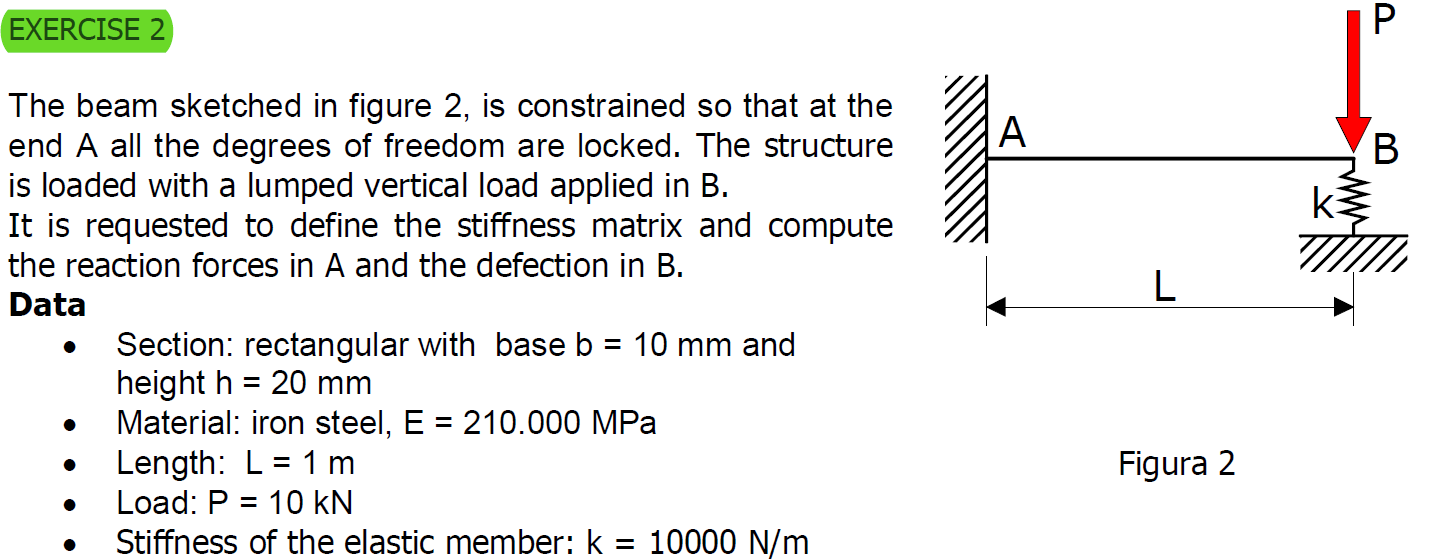

syms K E l I k w
format bank

l=1

l =           1.00


E=2*10^11

E =  200000000000.00


I=7.5*10^-7

I =           0.00



J=.2

J =           0.20


k=100*10^3

k =      100000.00


m=20

m =          20.00


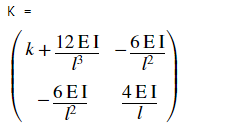

K=(E*I/l^3)*[ 12 -6;
              -6 4];
K(1,1)=K(1,1)+k

K =     1900000.00    -900000.00
    -900000.00     600000.00


K

K =     1900000.00    -900000.00
    -900000.00     600000.00



% Mcond=m+9/4*J/l

Mcond =          20.45


% Kcond=(12+k+9/l)*E*I/l^3*10^-6

Kcond =       15003.15


% w=sqrt(Kcond/Mcond)

w =          27.09




M=[m 0;0 J]

M =          20.00             0
             0          0.20


K

K =     1900000.00    -900000.00
    -900000.00     600000.00



syms w
% w_con=sqrt(Kcond/Mcond)

w_sol=solve(det(K-w^2*M)==0)

$$w\_sol = \left(\begin{array}{c} \sqrt{1547500-2500\,\sqrt{369961}}\\ \sqrt{2500\,\sqrt{369961}+1547500}\\ -\sqrt{1547500-2500\,\sqrt{369961}}\\ -\sqrt{2500\,\sqrt{369961}+1547500} \end{array}\right)$$

double(w_sol)

ans =         163.98
       1751.60
       -163.98
      -1751.60


double(w_sol/(2*pi()))

ans =          26.10
        278.78
        -26.10
       -278.78
